Client is connected


Ball out of field


Last touch = Robot1: 1

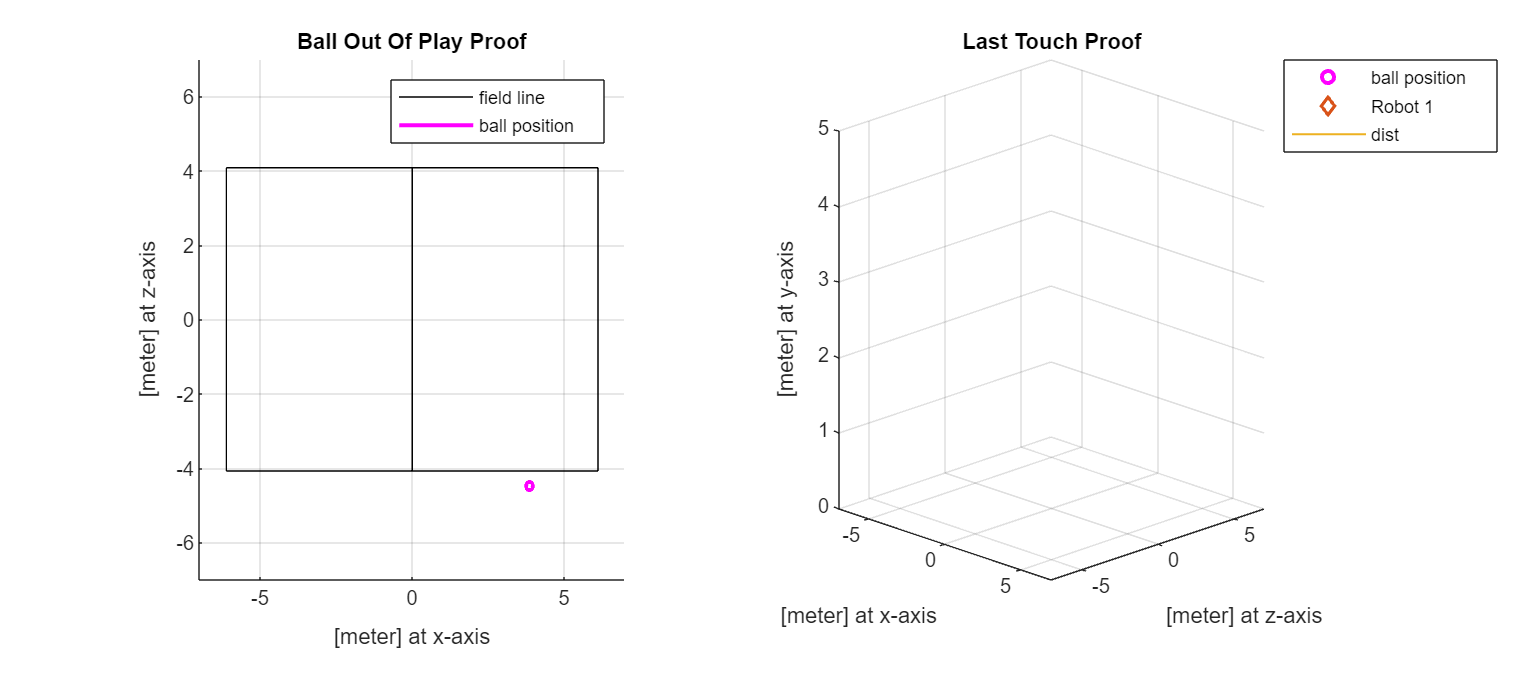

m_state = 0;
while true
    switch m_state
        % Initialization
        case 0
            % add path for the helper functions
            addpath("helper_functions\")

            % initialize parallel pool for parallel processing
            % parpool
            
            % create cleanup object when ctrl+c is called
            cleanupObj = onCleanup(@cleanMainUp);
    
            % Import Machine Learning model from Python
            py.importlib.import_module('joblib');
            py.importlib.import_module('sklearn.ensemble');
    
            % Create NatNet client and connect to server
            nnc = setNNC('Unicast','192.168.6.232','192.168.5.101');
    
            % Parameters
            sample_freq = 100;
            field_corners = [-4.08 4.08;-6.12 6.12];
            ball_radius = 11e-2;
            ballID = 998;
            robot1ID = 1007;
            robot2ID = 0;
            robot3ID = 0;
            robot4ID = 0;

            % Create figure for proof
            [f, t] = createProofFig();

            % Change m_state to Set temporary data if no error in nnc connection
            if nnc.IsConnected
                m_state = 1;
                % disp('Press space to continue')
                % waitforbuttonpress;
            end

        % Set temporary data to initial state
        case 1
            % Temporary data
            prev_data = [];
            last_touch_data = [];
            % last_touch = zeros(1,4);
            last_touch = zeros(1,1);
            ball_inside = true;
            getDataT = 0.01;            % Make the first time to run immediately
            decisionMakingT = 0.01;     % Make the first time to run immediately

            % Change state to Get data
            m_state = 2;
    
        % Get data
        case 2
            try
                % Make runtime of get data and decision making at least the
                % same with sampling time
                if getDataT + decisionMakingT >= 1/sample_freq
                    current_data = nncPollAll(nnc);
                else
                    sampT = round((getDataT + decisionMakingT)*1000);
                    java.lang.Thread.sleep(round(996/sample_freq)-sampT);
                    current_data = nncPollAll(nnc);
                end

                % Start timer to measure Get data runtime
                tic
        
                % Get another data only if it's not the first data and it's not
                % within radius of the previous data, 3 attempts
                for i = 1:3
                    % If after 3 attempts the data points still "jump", use the
                    % last one
                    if ~isempty(prev_data) && ~checkWithinRadius(prev_data, current_data)
                        % To make sure the data is not the same
                        java.lang.Thread.sleep(round(996*(1/sample_freq/5)));
                        current_data = nncPollAll(nnc);
                    else
                        break
                    end
                end
        
                % ball array for BOOP
                [~, col] = find(current_data == ballID);
                ball_pos = [current_data(1,col) current_data(3,col)];      % [x z]
        
                % ball and robots table for ML model
                T_ball_turtle1 = makeBallTurtleTable(current_data, ballID, robot1ID);
                % T_ball_turtle2 = makeBallTurtleTable(current_data, ballID, robot2ID);
                % T_ball_turtle3 = makeBallTurtleTable(current_data, ballID, robot3ID);
                % T_ball_turtle4 = makeBallTurtleTable(current_data, ballID, robot4ID);
    
                % Change state to decision making, all data has been checked inside nncPollAll
                m_state = 3;

                % End timer to measure Get data runtime
                getDataT = toc;

            catch
                warning( '\tPacket is empty/stale\n' )
                warning( '\tMake sure the server is in Live mode or playing in playback\n\n')
                
                % Change state back to initialization
                m_state = 0;
                disp('Press space to continue')
                % waitforbuttonpress;
            end
    
        % Decision making
        case 3
            % Start timer to measure Decision making runtime
            tic

            % Run last touch function with output [0/1 0/1 0/1 0/1]
            turtleTouch1 = predict_touch(T_ball_turtle1);
            % turtleTouch2 = predict_touch(T_ball_turtle2);
            % turtleTouch3 = predict_touch(T_ball_turtle3);
            % turtleTouch4 = predict_touch(T_ball_turtle4);
            % current_last_touch = [turtleTouch1 turtleTouch2 turtleTouch3 turtleTouch4];
            current_last_touch = turtleTouch1;
            
            % Run BOOP function
            ball_inside = BOOP_Naive(ball_pos, field_corners, ball_radius);

            % Show which robot touch the last if ball out of field
            if ~ball_inside
                disp("Ball out of field")
                % fspec = "Last touch = Robot1: %d, Robot2: %d, Robot3: %d, Robot4: %d";
                % fprintf(fspec, last_touch)
                fspec = "Last touch = Robot1: %d";
                fprintf(fspec, last_touch)

                % Ask users if they want proof, default set to no
                % disp("Press space within 5 seconds to show proof")
                % [CH, ~] = getkeywait(5);        % Space output 32
                % if CH == 32
                %     % Show proof for BOOP
                %     BOOP_plot(field_corners,ball_pos,ball_radius,t)
                % 
                %     % Show proof for Last Touch
                %     LastTouch_plot(t, last_touch_data, last_touch, ballID, robot1ID, robot2ID, robot3ID, robot4ID)
                % 
                %     % use "waitfor" to wait for the user to close the
                %     % figure to continue, or use waitforbuttonpress
                %     % disp('Press space to continue')
                %     % waitforbuttonpress
                %     % clf(f)
                % 
                %     % Change state back to Set temporary data
                %     m_state = 1;
                % end
                % Show proof for BOOP
                BOOP_plot(field_corners,ball_pos,ball_radius,t)

                % Show proof for Last Touch
                LastTouch_plot(t, last_touch_data, last_touch, ballID, robot1ID, robot2ID, robot3ID, robot4ID)

                % Change state back to Set temporary data
                m_state = 1;

            else
                % Save the last one who touch the ball if the ball is
                % inside
                if any(current_last_touch == 1)
                    last_touch = current_last_touch;
                    last_touch_data = current_data;
                end

                % Save current data to previous data
                prev_data = current_data;

                % Change state back to get data
                m_state = 2;
            end

            % End timer to measure Decision making runtime
            decisionMakingT = toc;
    end
end

function cleanMainUp()
    % clear data
    % clear and close figures
    clf
    close

    % Shutdown parallel pool
    % poolObj = gcp('nocreate');
    % delete(poolObj)
    
end